assert(endsWith(pwd, "\ferromagnetic metal disk in time domain"), 'Not in project directory')
addpath('../../DCS_functions')

clear;
close all;

## Distributed Current Source

#### Electromagnet

Coil.num = 1;
Coil.inner_radius = 3.75e-3; % (m)
Coil.outer_radius = 6.00e-3; % (m)
Coil.length       = 4.00e-3; % (m)
Coil.z            = 5.00e-3; % (m)

Coil.wire_diameter = 0.35e-3; % (m)
Coil.N_turns = 60;
Coil.conductivity = 6e7; % (S/m)
Coil.series_resistance = 0; % (Ohm)

#### Sensor

Sensor.num = 1;
Sensor.side_length = 0.8e-3;

Sensor.position = [0e-3 2.5e-3]';

#### Model

disk.radius = 30e-3; % (m)
disk.height = 6e-3; % (m)
disk.n_r = 30; % number of elements in r direction
disk.n_z = 10; % number of elements in z direction

r = linspace(0, disk.radius, disk.n_r+1);
z = linspace(-disk.height,0, disk.n_z+1);

Model = BuildModel2D('Cylinder', r,z);

build model took 0.02 seconds


clear disk r z

Model.conductivity = 1.45e6 * ones(1,Model.num_elms); % (S/m)
Model.relative_permeability = 50 * ones(1,Model.num_elms); % (1)
Model.relative_permittivity = 1 * ones(1,Model.num_elms); % (1)

#### Governing equation

GoverningEquation = BuildGoveringEquation2D(Model, Coil, Sensor);

build governing equation took 44.90 seconds


#### Solve in time domain

V_E = 1; % (V)
pulse_width = 3e-3; % (s)
Coil.time_domain.voltage = @(t) V_E * (t <= pulse_width);
clear V_E pulse_width

% I_E = 1; % (A)
% f = 500; % (Hz)
% omega = 2*pi*f;
% Coil.time_domain.current      = @(t) I_E * sin(omega * t);
% Coil.time_domain.current_diff = @(t) I_E * omega * cos(omega * t);
% clear I_E f omega

Coil.time_domain.time_span = [0, 5e-3]; % (s)
[Model, Coil, Sensor] = SolveTimeDomain2D(GoverningEquation, Model, Coil, Sensor);

solve in time domain took 0.68 seconds


#### Plot result

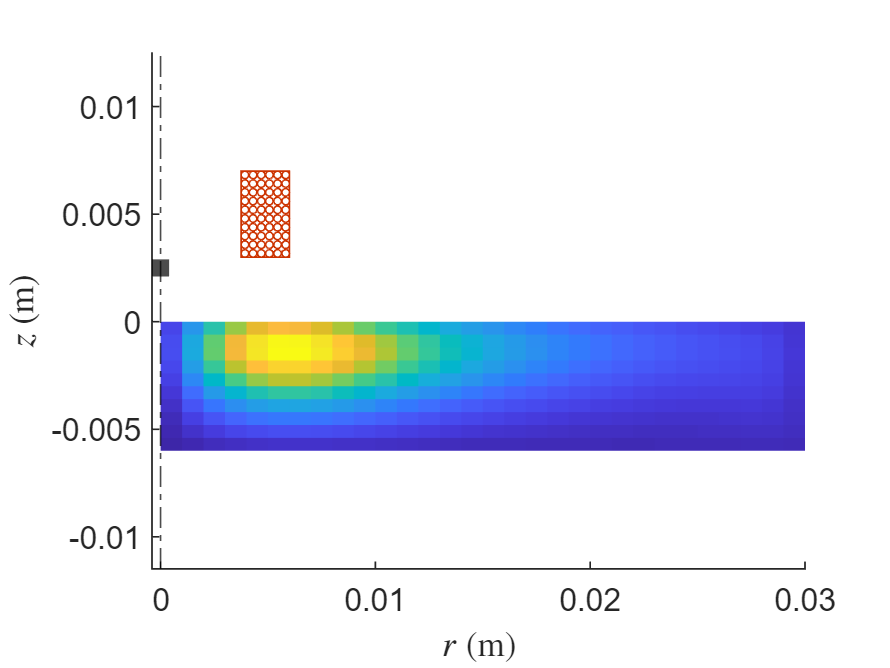

t = 0.3e-3; % (s)
[~,k] = min(abs(t - Model.time_domain.t));
PlotWorld2D(Model, Coil, Sensor, abs(Model.time_domain.J(:,:,k)) );

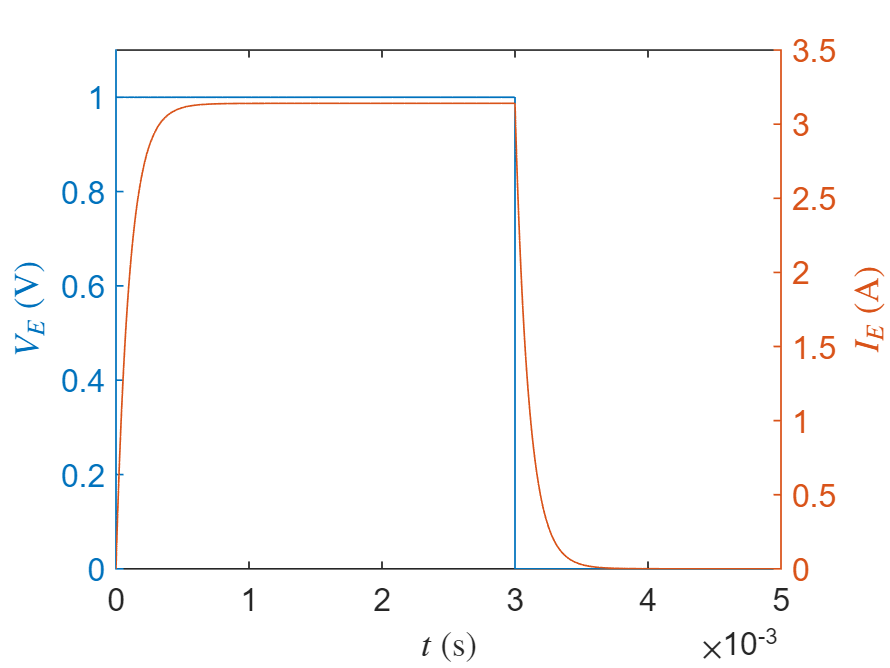

clf
clear t k


if isfield(Coil.time_domain, 'current')
plot(Sensor.time_domain.t, squeeze(Coil.time_domain.I));
xlabel('$t$ (s)', 'Interpreter','latex')
ylabel('$I_E$ (V)', 'Interpreter','latex')
clf
end

if isfield(Coil.time_domain, 'voltage')
V = Coil.time_domain.voltage(Sensor.time_domain.t);
yyaxis left
plot(Sensor.time_domain.t, V)
ylim([-inf, max(V)*1.1])
ylabel('$V_E$ (V)', 'Interpreter','latex')
yyaxis right
plot(Sensor.time_domain.t, squeeze(Coil.time_domain.I));
ylabel('$I_E$ (A)', 'Interpreter','latex')
xlabel('$t$ (s)', 'Interpreter','latex')
clf
clear V
end

## Compare with FEA

#### Current density

data = readmatrix('FEA_data/J.csv', 'CommentStyle','%');
data = reshape(data(3:end), 2, []);
FEA.t = data(1,:);
FEA.J = data(2,:);
    
j = 275;
display(Model.elms_center(:,j))

    0.0045
   -0.0003



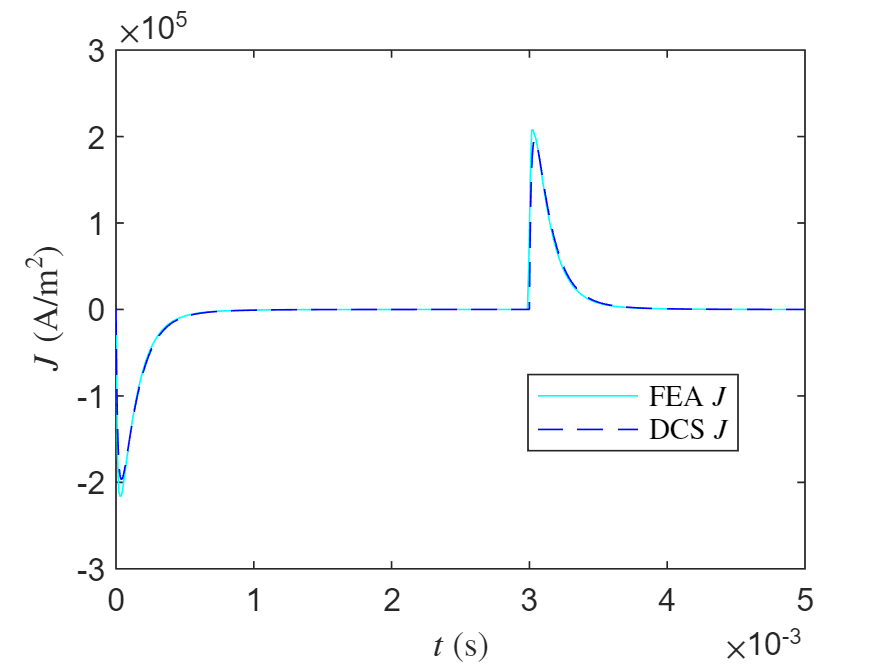

plot(FEA.t, FEA.J, 'c-', 'DisplayName','FEA $J$'); hold on
plot(Model.time_domain.t, squeeze(Model.time_domain.J(1,j,:)), 'b--', 'DisplayName','DCS $J$')
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$t$ (s)", 'Interpreter','latex')
ylabel("$J$ (A/m$^2$)", 'Interpreter','latex')
hold off

clf

clear j

#### Magnetic flux density

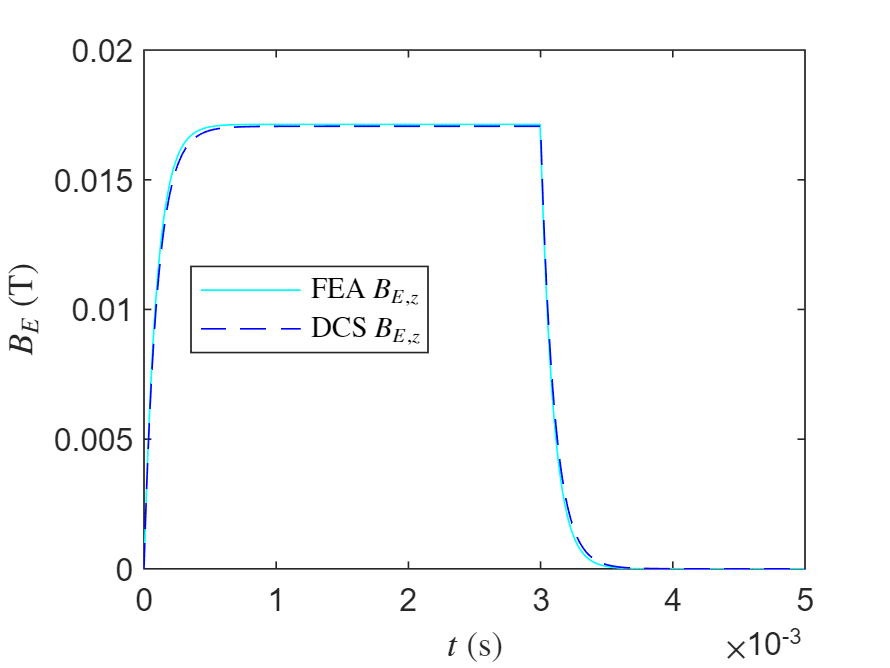

data = readmatrix('FEA_data/B_E.csv', 'CommentStyle','%');
data = reshape(data(3:end), 3, []);
FEA.t = data(1,:);
FEA.B_E_r = data(2,:);
FEA.B_E_z = data(3,:);
data = readmatrix('FEA_data/B_mur50.csv', 'CommentStyle','%');
data = reshape(data(3:end), 3, []);
FEA.B_C_r = data(2,:) - FEA.B_E_r;
FEA.B_C_z = data(3,:) - FEA.B_E_z;

plot(FEA.t, FEA.B_E_z, 'c-', 'DisplayName','FEA $B_{E,z}$'); hold on
plot(Sensor.time_domain.t, squeeze(Sensor.time_domain.B_E(2,1,:)), 'b--', 'DisplayName','DCS $B_{E,z}$');
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$t$ (s)", 'Interpreter','latex')
ylabel("$B_E$ (T)", 'Interpreter','latex')
hold off

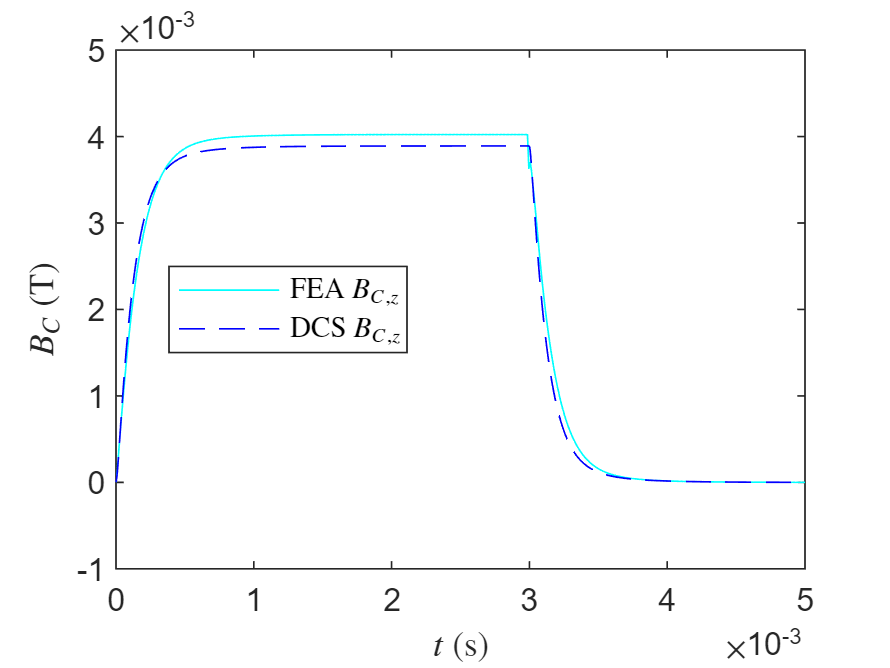

clf

plot(FEA.t, FEA.B_C_z, 'c-', 'DisplayName','FEA $B_{C,z}$'); hold on
plot(Sensor.time_domain.t, squeeze(Sensor.time_domain.B_C(2,1,:)), 'b--', 'DisplayName','DCS $B_{C,z}$');
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$t$ (s)", 'Interpreter','latex')
ylabel("$B_C$ (T)", 'Interpreter','latex')
hold off

clf

FEA_B_C_z = FEA.B_C_z;
DCS_B_C_z = interp1(Sensor.time_domain.t, squeeze(Sensor.time_domain.B_C(2,1,:)), FEA.t);
[error, i] = maxk(abs(DCS_B_C_z - FEA_B_C_z), 100);
relative_error = mean(abs(error ./ FEA_B_C_z(i)));
fprintf('average relative error: %e\n', relative_error);

average relative error: 8.855827e-02



clear data FEA_B_C_z DCS_B_C_z relative_error error i

## Material Sweep

#### Solve in time domain

permeability = [50  60  70  80  90 ];
colors       = ['r' 'g' 'b' 'k' 'y'];

hold on
for i = 1:numel(permeability)
    Model.relative_permeability = permeability(i) * ones(1,Model.num_elms);
    GoverningEquation = BuildGoveringEquation2D(GoverningEquation, Model);

    [Model, Coil, Sensor] = SolveTimeDomain2D(GoverningEquation, Model, Coil, Sensor);

    plot(Sensor.time_domain.t, squeeze(Sensor.time_domain.B(2,1,:)), '-', 'DisplayName',sprintf('$\\mu_r$ = %d',permeability(i)), 'Color',colors(i));
end

solve in time domain took 0.55 seconds
solve in time domain took 0.58 seconds
solve in time domain took 0.65 seconds
solve in time domain took 0.61 seconds
solve in time domain took 0.61 seconds


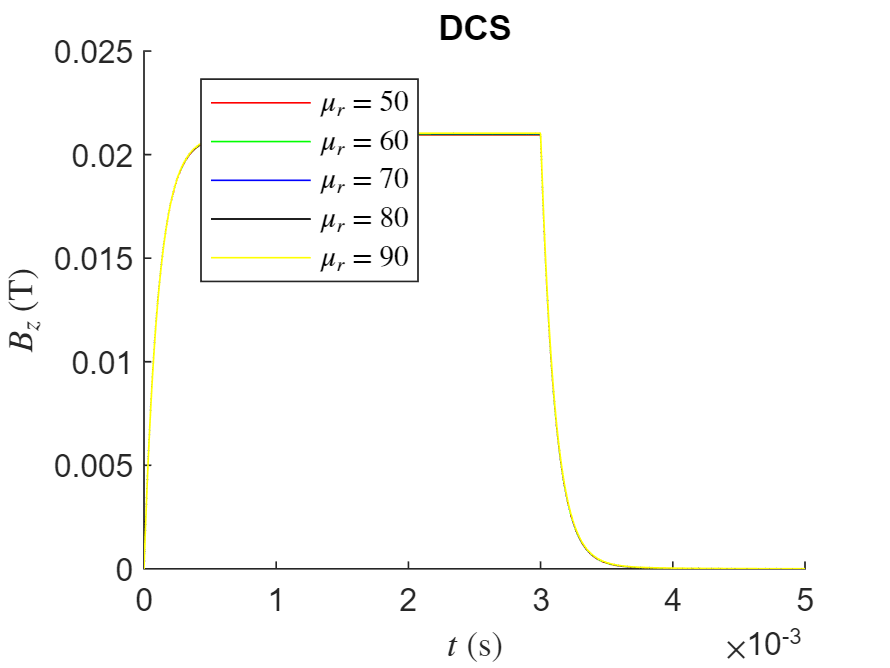

title('DCS')
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$t$ (s)", 'Interpreter','latex')
ylabel("$B_z$ (T)", 'Interpreter','latex')
hold off

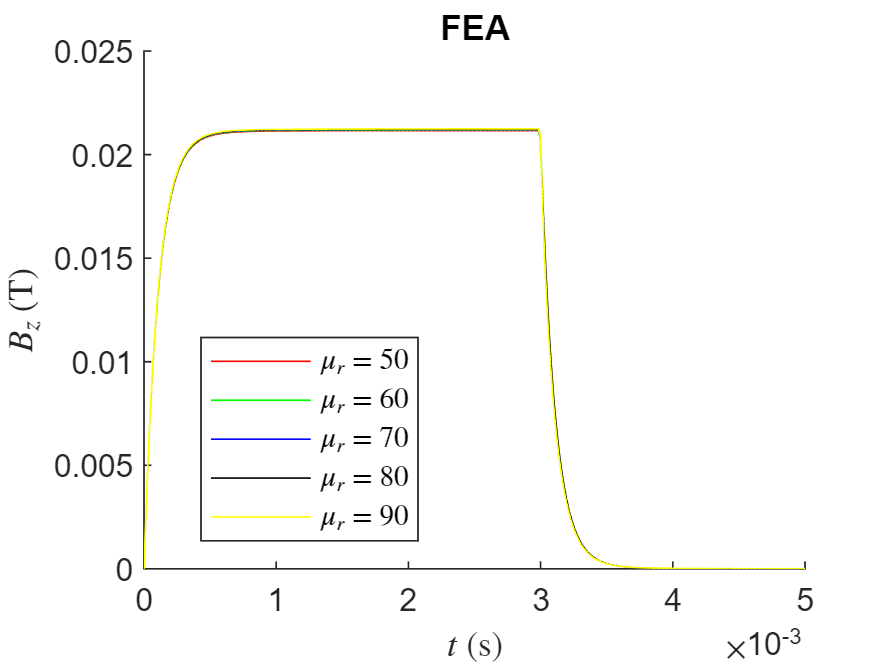

clf

hold on
for i = 1:numel(permeability)
    data = readmatrix(sprintf('FEA_data/B_mur%d.csv',permeability(i)), 'CommentStyle','%');
    data = reshape(data(3:end), 3, []);

    plot(data(1,:), data(3,:), '-', 'DisplayName',sprintf('$\\mu_r$ = %d',permeability(i)), 'Color',colors(i));
end
title('FEA')
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$t$ (s)", 'Interpreter','latex')
ylabel("$B_z$ (T)", 'Interpreter','latex')
hold off

clf

clear permeability colors i data